# **Classification using Fisher's Iris Data**

Copyright@ *Nabajeet Barman (nabajeetbarman4@gmail.com)*

`NOTE`: Multi-class classification using the Classification Learner App is not supported for Logistic Regression but does work for other algorithms. [**mnrfit**](https://in.mathworks.com/help/stats/mnrfit.html) does the Multinomial Logistic Regression, you may use [**glmfit**](https://in.mathworks.com/help/stats/glmfit.html#btwfzuj-1) with corresponding distribution for doing the same.  A possible solution is actually the "One vs All" where one class is denoted by 1 and the rest of the classes becomes 0. Then the problem is treated as a binary classification problem.

## Objective: (Multi-class) classification using Fisher's Iris Data

Fisher's iris data consists of measurements on the **sepal length**, **sepal width**, **petal length**, and** petal width** for 150 iris specimens. There are 50 specimens from each of three species.

**Problem Statement**: It is a **multi-class classification** problem. The number of observations for each class is **balanced**. There are 150 observations with 4 input variables and 1 output variable. The variable names are as follows:

- Sepal length in cm.

- Sepal width in cm.

- Petal length in cm.

- Petal width in cm.

- Class (Iris Setosa, Iris Versicolour, Iris Virginica).

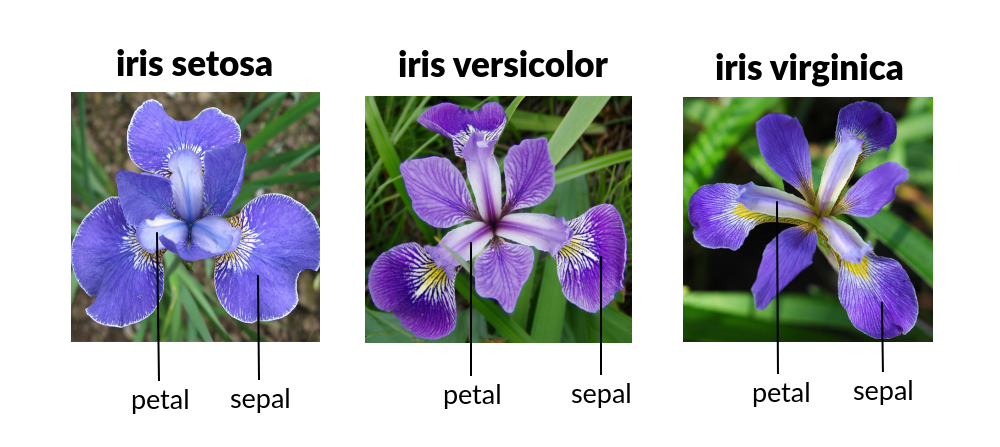

close all; clear; clc 
%%load divided input data set 
load fisheriris

Check the input and output variable

% input variables
meas;
% output variable
species;

### View the dataset

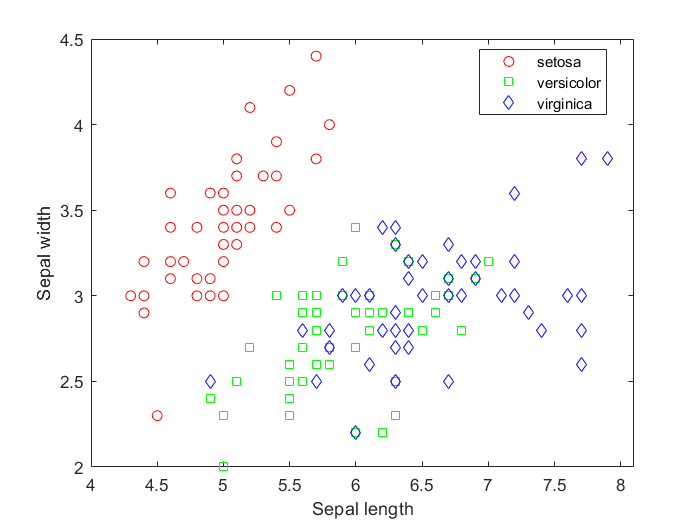

f = figure;
gscatter(meas(:,1), meas(:,2), species,'rgb','osd'); % o= circle, s= square,  d= diamond refers to marker symbols
xlabel('Sepal length');
ylabel('Sepal width');

N = size(meas,1);

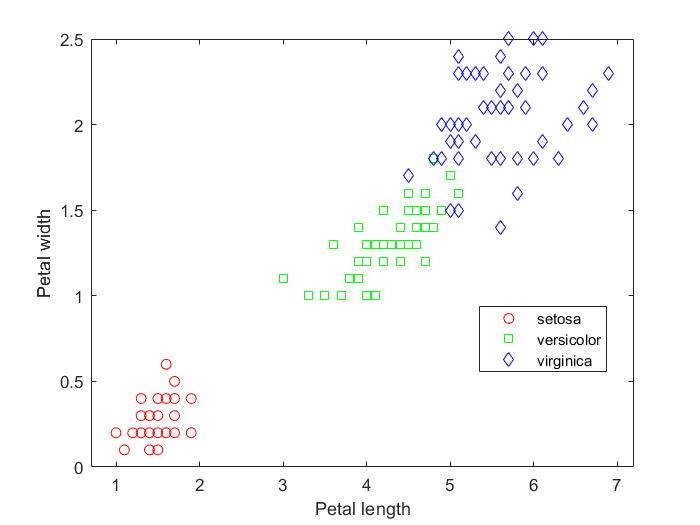

% TODO: View the plot of Petal length vs Petal width
f = figure;
gscatter(meas(:,3), meas(:,4), species,'rgb','osd');
xlabel('Petal length');
ylabel('Petal width');

# Neural Network Start tool

# 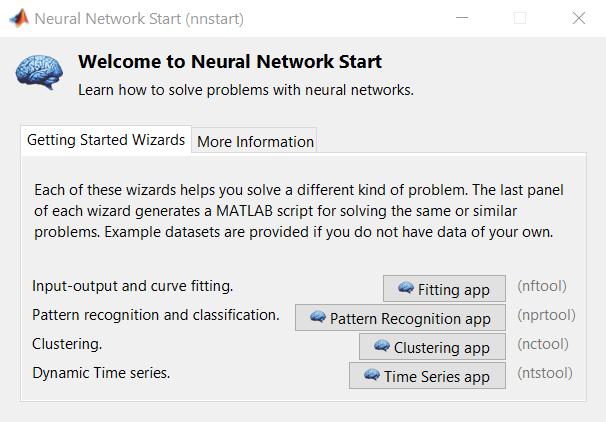

# nprtool - Neural Net Pattern Recognition tool

`nprtool` leads you through solving a pattern-recognition classification problem using a two-layer feed-forward [`patternnet`](https://localhost:31515/static/help/deeplearning/ref/patternnet.html) network with sigmoid output neurons. 

Pattern recognition networks are feedforward networks that can be trained to classify inputs according to target classes. The target data for pattern recognition networks should consist of vectors of all zero values except for a 1 in element i, where i is the class they are to represent.

Feedforward networks often have one or more hidden layers of sigmoid neurons followed by an output layer of linear neurons. Multiple layers of neurons with nonlinear transfer functions allow the network to learn nonlinear relationships between input and output vectors. **A full documentation is available on Box **[here](https://kingston.box.com/s/e58njna8pvm34k9txvky8tteettrdof4).

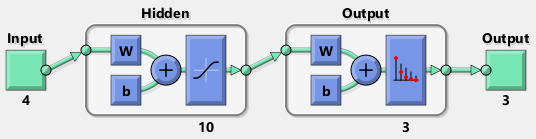

**GUI example using Iris dataset**

clear; 
close all; 
clc;
[inputs,targets] = iris_dataset;
nprtool

`The linear output layer is most often used for function fitting (or nonlinear regression)` `problems`. `On the other hand, if you want to constrain the outputs of a network (such as between 0 and 1), then the output layer should use a sigmoid transfer function (such as logsig). This is the case when the network is used for pattern recognition problems (in which case a decision is being made by the network)`.

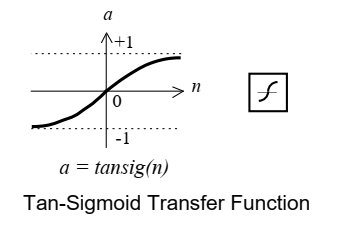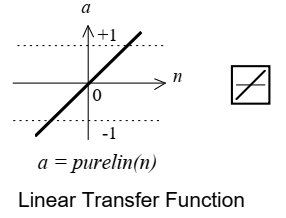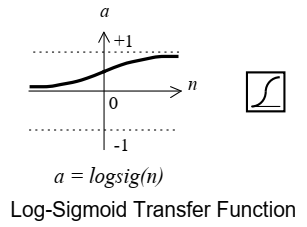

**Sigmoid output neurons are often used for pattern recognition problems, while linear output neurons are used for function fitting problems. Multilayer networks often use the log-sigmoid transfer function **`logsig`**.**

**Complexity**: 

More neurons require more computation, and they have a tendency to overfit the data when the number is set too high, but they allow the network to solve more complicated problems. More layers require more computation, but their use might result in the network solving complex problems more efficiently. **To use more than one hidden layer, enter the hidden layer sizes as elements of an array in the patternnet command.**

**Note: **Networks are also sensitive to the number of neurons in their hidden layers. Too few neurons can lead to underfitting. Too many neurons can contribute to overfitting, in which all training points are well fitted, but the fitting curve oscillates wildly between these points.  

#### **Training Algorithm(s):**

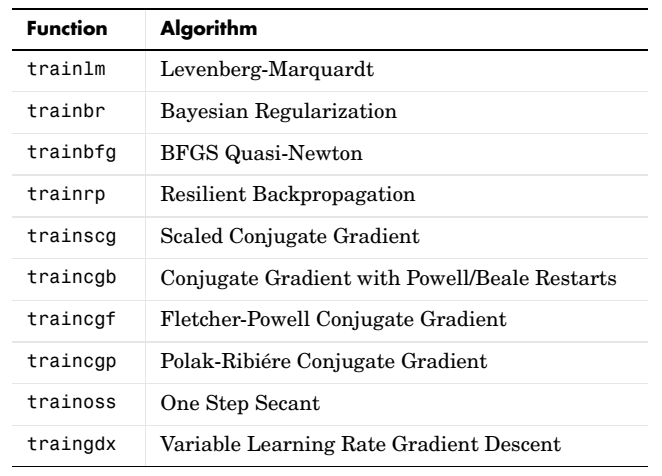

 

The fastest training function is generally `trainlm`, and it is the default training function for `feedforwardnet`. The **Broyden–Fletcher–Goldfarb–Shanno** (**BFGS**) **quasi**-**Newton** method, `trainbfg`, is also quite fast. Both of these methods tend to be less efficient for large networks (with thousands of weights), since they require more memory and more computation time for these cases. Also, `trainlm` performs better on function fitting (nonlinear regression) problems than on pattern recognition problems. When training large networks, and when training pattern recognition networks, `trainscg` and `trainrp` are good choices. Their memory requirements are relatively small, and yet they are much faster than standard gradient descent algorithms.

**For our classification task, we will use: **`trainscg (default)`

`trainscg` can train any network as long as its weight, net input, and transfer functions have derivative functions. Backpropagation is used to calculate derivatives of performance `perf` with respect to the weight and bias variables `X`. The scaled conjugate gradient algorithm is based on conjugate directions, as in `traincgp`, `traincgf`, and `traincgb`, but this algorithm does not perform a line search at each iteration. See [Moller (Neural Networks, Vol. 6, 1993, pp. 525–533)](https://www.sciencedirect.com/science/article/abs/pii/S0893608005800565) for a more detailed discussion of the scaled conjugate gradient algorithm.

**Note**: As a note on terminology, the term “*backpropagation*” is sometimes used to refer specifically to the gradient descent algorithm, when applied to neural network training. That terminology is not used here (in MATLAB documentation), since the process of computing the gradient and Jacobian by performing calculations backward through the network is applied in all of the training functions listed above. It is clearer to use the name of the specific optimization algorithm that is being used, rather than to use the term backpropagation alone. 

Training stops when any of these conditions occurs:

- The maximum number of `epochs` (repetitions) is reached.

- The maximum amount of `time` is exceeded.

- Performance is minimized to the `goal`.

- The performance gradient falls below `min_grad`.

- Validation performance has increased more than `max_fail` times since the last time it decreased (when using validation).

When training multilayer networks, the general practice is to first divide the data into three subsets. The first subset is the `training set`, which is used for computing the gradient and updating the network weights and biases. The second subset is the `validation set`. The error on the validation set is monitored during the training process. The validation error normally decreases during the initial phase of training, as does the training set error. However, when the network begins to overfit the data, the error on the validation set typically begins to rise. `The network weights and biases are saved at the minimum of the validation set error`.  

Generally, the error reduces after more epochs of training, but might start to increase on the validation data set as the network starts overfitting the training data. **In the default setup, the training stops after six consecutive increases in validation error**, and the best performance is taken from the epoch with the lowest validation error.

#### Model Performance:

**(In general)** If you are dissatisfied with the network’s performance on the original or new data, you can **train it again**, increase the number of neurons, or perhaps get a larger training data set.

(for classification problems) If you needed even more accurate results, you could try any of the following approaches: 

- Reset the initial network weights and biases to new values with `init` and train again. 

- Increase the number of hidden neurons. 

- Increase the number of training vectors. 

- Increase the number of input values, if more relevant information is available. 

- Try a different training algorithm

If the performance on the training set is good, but the test set performance is significantly worse, which could indicate overfitting, then reducing the number of neurons can improve your results. If training performance is poor, then you may want to increase the number of neurons.

**Confusion Matrix**

Unlike binary classification, there are no positive or negative classes here. At first, it might be a little difficult to find TP, TN, FP and FN since there are no positive or negative classes.

             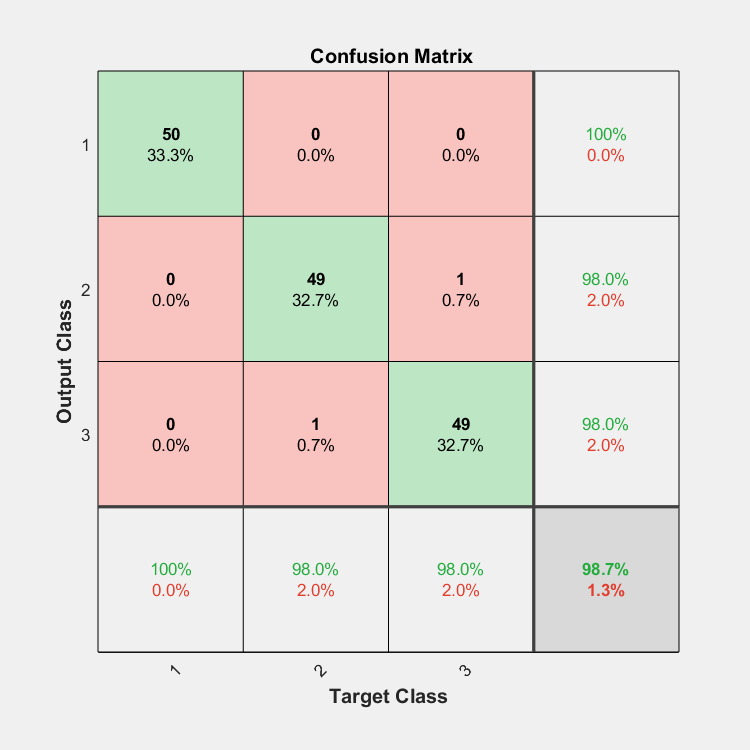

The **rows** correspond to the** predicted class (Output Class)** and the **columns** correspond to the **true class (Target Class)**. The diagonal cells correspond to observations that are correctly classified. The off-diagonal cells correspond to incorrectly classified observations. Both the number of observations and the percentage of the total number of observations are shown in each cell. The column on the far right of the plot shows the percentages of all the examples predicted to belong to each class that are correctly and incorrectly classified. These metrics are often called the precision (or positive predictive value) and false discovery rate, respectively. The row at the bottom of the plot shows the percentages of all the examples belonging to each class that are correctly and incorrectly classified. These metrics are often called the recall (or true positive rate) and false negative rate, respectively. The cell in the bottom right of the plot shows the overall accuracy.

`Important!!! The axis are transposed in the confusion matrix in the Classification Learner App`

             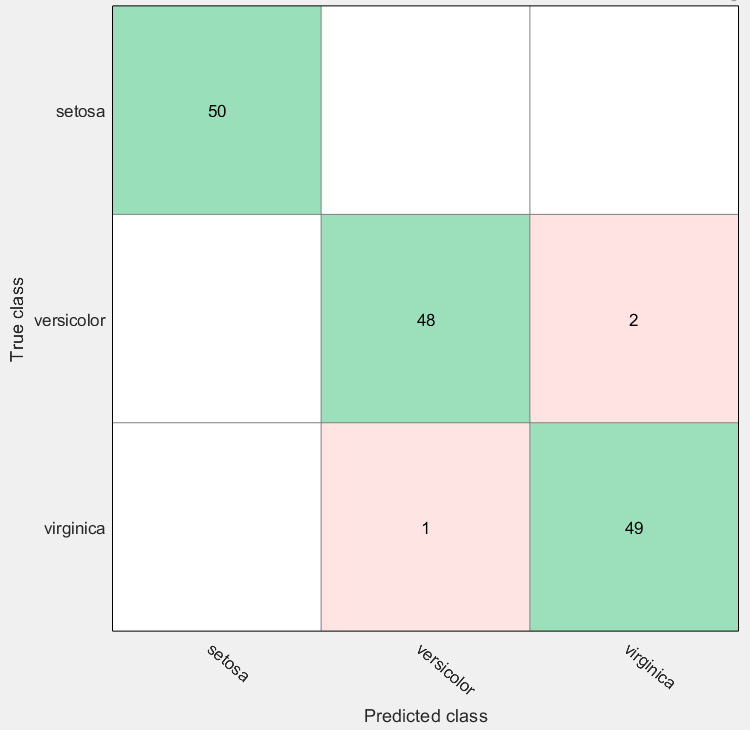

## Classifying patterns using a Shallow Neural Network (Code)

% Solving a pattern recognition problem with a Neural Network
% The following data is expected for the program to work!!!
%   x - input data.
%   r - target data.
clear; 
close all; 
clc;
[inputs,targets] = iris_dataset;

% Choose a Training Function
% For a list of all training functions type: help nntrain
% 'trainlm' is usually fastest.
% 'trainbr' takes longer but may be better for challenging problems.
% 'trainscg' uses less memory. Suitable in low memory situations.

trainFcn = 'trainscg';  % Scaled conjugate gradient backpropagation.
% this is the default one, hence skipping this would anyway set the
% training function to trainscg

% Create a Pattern Recognition Network
hiddenLayerSize = 10;
net = patternnet(hiddenLayerSize);

% Divide the data into training, validation, and test
% For a list of all data division functions type: help nndivision
net.divideFcn = 'dividerand';  % Divide data randomly
net.divideMode = 'sample';  % Divide up every sample
net.divideParam.trainRatio = 70/100;
net.divideParam.valRatio = 15/100;
net.divideParam.testRatio = 15/100;

% Choose a Performance Function
% For a list of all performance functions type: help nnperformance
net.performFcn = 'crossentropy';  % Cross-Entropy #default!!!

% Train the Network
[net,tr] = train(net,inputs,targets);

% Test the Network. After the network has been trained, you can use it to compute the network outputs. 
% The following code calculates the network outputs, errors and overall performance. 
outputs = net(inputs);
errors = gsubtract(targets,outputs); 
% gsubtract(a,b) takes two matrices or cell arrays, and subtracts them in an element-wise manner.
overall_performance = perform(net,targets,outputs)

overall_performance = 0.0302

tind = vec2ind(targets);
yind = vec2ind(outputs);
percentErrors = sum(tind ~= yind)/numel(tind)

percentErrors = 0.0267

% Recalculate Training, Validation and Test Performance
trainTargets = targets .* tr.trainMask{1};
valTargets = targets .* tr.valMask{1};
testTargets = targets .* tr.testMask{1};
train_performance = perform(net,trainTargets,outputs)

train_performance = 1.2518

val_performance = perform(net,valTargets,outputs)

val_performance = 3.6203

test_performance = perform(net,testTargets,outputs)

test_performance = 3.5379

% View the Network
view(net)
% Plots
% Uncomment these lines to enable various plots.
% For a list of all plot functions type: help nnplot
% figure, plotperform(tr)
% figure, plottrainstate(tr)
% figure, plotconfusion(targets,outputs)
% figure, ploterrhist(errors)

# Workshop Tasks (self practice)

MATLAB provides Italian wine dataset. This dataset can be used to create a neural network that classifies wines from three winerys in Italy based on constituents found through chemical analysis.

The Wine Quality Dataset involves predicting the quality of white wines on a scale given chemical measures of each wine.It is a **multi-class classification problem** but could also be framed as a regression problem. 

    ***wineInputs*** - a 13x178 matrix of thirteen attributes of 178 wines.

-  Alcohol

-  Malic acid

-  Ash

-  Alcalinity of ash  

-  Magnesium

-  Total phenols

-  Flavanoids

-  Nonflavanoid phenols

-  Proanthocyanins

-  Color intensity

-  Hue

-  OD280/OD315 of diluted wines

-  Proline

***wineTargets*** - a 3x178 matrix of 7200 associated class vectors defining which of three classes each input is assigned to. Classes are represented by a 1 in row 1, 2 or 3.

-  Vinyard #1

-  Vinyard #2

-  Vinyard #3

 [X,T] = wine_dataset loads the inputs and targets into variables of your own choosing.

`Use the MATLAB GUI to analyze and perform classification using this dataset.`

Be cautioned that although a multilayer backpropagation network with enough neurons can implement just about any function, backpropagation does not always find the correct weights for the optimum solution. You might want to reinitialize the network and retrain several times to guarantee that you have the best solution.

`Generate the code from the GUI and repeat the training, test and validation process 8 times (hint: use a for loop and calculate the average performance results!!!!).`